bag_dir = "~/tagslam_ws/tagslam_root/src/continuum_mocap/bags/benchmarks/localized";

test_1 = bag_dir + "/localized-test_1_moving_2021-12-11-01-14-57.bag";
test_2 = bag_dir + "/localized-test_2_moving_2021-12-11-01-23-21.bag";
bag_1 = rosbag(test_1);
bag_2 = rosbag(test_2);

disp_bag(bag_1)

tag_0
   -0.0000    0.1524    0.0000
   1.0e-18 *
    0.1340   -0.0741   -0.0284
tag_1
    0.0351    0.1526   -0.0004
    0.1590    0.0674   -0.4257
tag_2
    0.0695    0.1528   -0.0007
    0.6508    0.4783   -0.4612
tag_3
    0.1052    0.1532   -0.0003
    0.3428    0.9666   -0.3973
tag_4
    0.1399    0.1539    0.0004
    0.8593   -1.6063    0.1983
tag_5
    0.1756    0.1550    0.0024
    1.3507   -2.7213   -0.6295
tag_6
    0.2059    0.0209    0.0008
    0.5355   -3.7040    0.1548
tag_7
    0.3115    0.0215    0.0017
    1.6997   -0.8934    0.6652
tag_8
   -0.0011    0.0193   -0.0026
    0.9212    0.1458   -0.2909
tag_9
    0.1027    0.0207   -0.0004
    0.3107   -0.7403   -2.1770


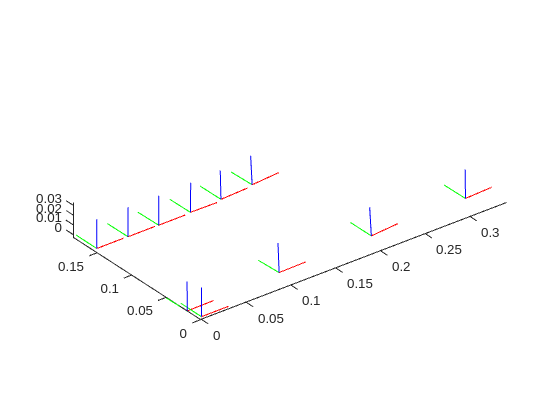

axis equal

disp_bag(bag_2)

tag_0
    0.0000    0.1524    0.0000
   1.0e-10 *
   -0.0373    0.0240    0.1219
tag_1
    0.0367    0.1527    0.0013
    0.1516   -2.8344   -0.9791
tag_2
    0.0722    0.1529    0.0020
    0.6750    1.0617   -1.6532
tag_3
    0.1091    0.1533    0.0038
    0.6881   -2.1496   -0.9304
tag_4
    0.1447    0.1536    0.0050
    0.6648   -0.1741   -0.8318
tag_5
    0.1814    0.1544    0.0087
    1.0235   -2.3252   -1.1680
tag_6
    0.2384    0.1048    0.0139
   45.3505   -1.3592   -5.8928
tag_7
    0.3228    0.0290    0.0119
    2.1838  -10.5431    1.4023
tag_8
    0.0001    0.0223    0.0046
   56.0960    1.6599   -4.2102
tag_9
    0.1575    0.0231    0.0089
   43.9869   -1.7118   -1.8096


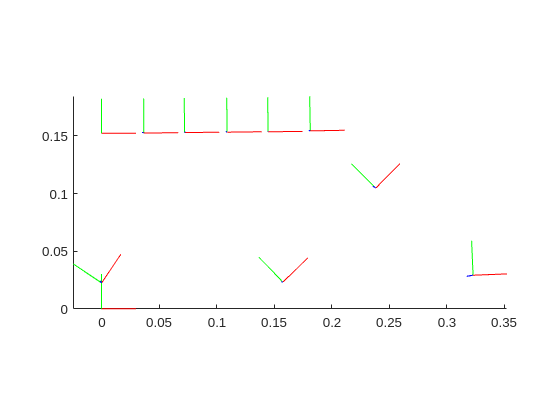

axis equal

function disp_bag(bag)
    posns = zeros([length(bag.AvailableFrames), 3]);
    quats = zeros([length(bag.AvailableFrames), 4]);

    for i = 1:length(bag.AvailableFrames)
        frame = bag.AvailableFrames{i};
        if startsWith(frame, "tag")
            disp(frame)
            tf_i = getTransform(bag, "map", frame).Transform;
    
            posn = [tf_i.Translation.X, tf_i.Translation.Y, tf_i.Translation.Z];
            eul = quat2eul(tf_i.Rotation.readQuaternion());
    
            disp(posn)
            disp(rad2deg(eul))

            posns(i, :) = posn;
            quats(i, :) = compact(tf_i.Rotation.readQuaternion());
        else
            posns(i, :) = [0, 0, 0];
            quats(i, :) = [1, 0, 0, 0];
        end
    end

    plotTransforms(posns, quats, FrameSize=0.03)
end